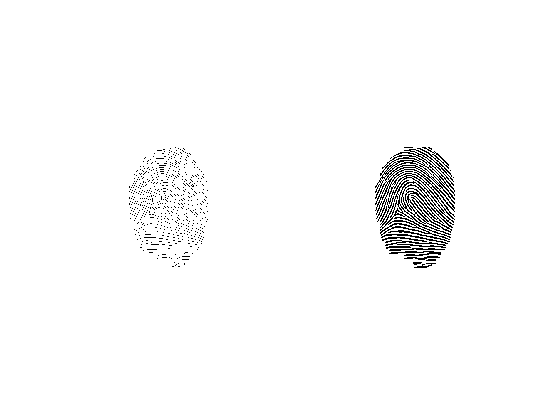

I = imread('r2_5.bmp');
I = im2double(I);
I = imbinarize(I,0.498);

se = strel('square',2);
Ic = imclose(I,se);%白的close是黑的open
%要清黑中白岛，白中黑岛
Ic = bwareaopen(Ic,50);
Ic = ~Ic;
Ic = bwareaopen(Ic,50);
Ic = ~Ic;
I_thin = ~bwmorph(~Ic,'thin',5);
%自己的剪H
%I_thin = my_H(I_thin);
%有点交叉点没连上的补上
%I_thin = my_cross(I_thin);
%不在细化图上去短线毛刺，毛刺会被既判定为端点又被判定为交叉点，通过这个来去

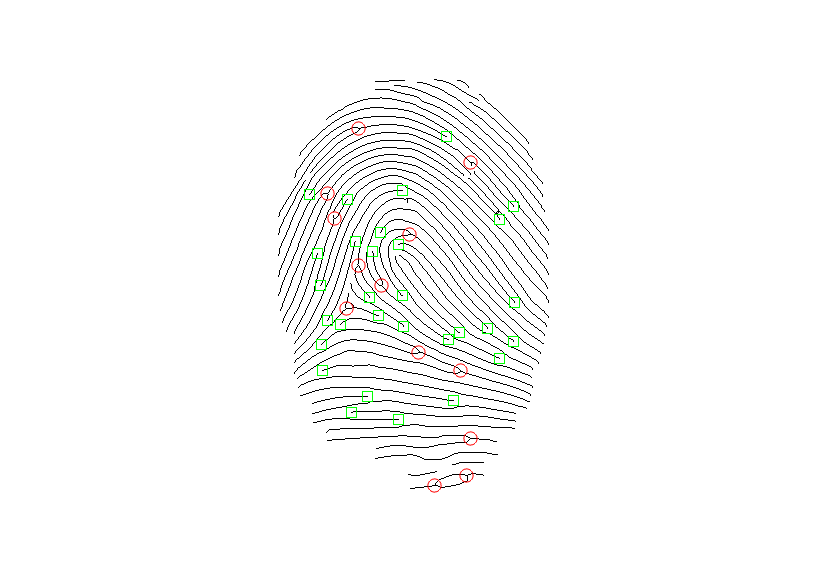


g1 = endpoints(~I_thin);
g2 = crosspoints(~I_thin);
I_final = im2double(I_thin);
figure(45);imshow(I_final);
[row1, col1] = find(g1);
[row2, col2] = find(g2);
%去因毛刺导致的端交叉点
%去挨在一起的端点（本该连着的）和挨在一起的交叉点（一个交叉点识别出多个）
%挨在一起的交叉点先去，因为它也可以是毛刺导致的重合，不然去毛刺后会留下一个
[row2, col2] = my_quchongcross(row2, col2);
[row1, col1, row2, col2] = my_spur(row1, col1, row2, col2);
[row1, col1] = my_quchongend(row1, col1);
%去边界
[row1, col1] = my_qubianjie(I_thin,row1, col1);

hold on, plot(col1,row1,'gs','MarkerSize',10);
hold on, plot(col2,row2,'ro','MarkerSize',10);

function I_H = my_H(I)
I_H = I;
for i = 1:size(I,1)-3
    for j = 1:size(I,2)-3
        if(I_H(i,j)==0 && I_H(i+1,j+1)==0 && I_H(i+2,j+2)==0)
             I_H(i+1,j) = 1;
             I_H(i,j+1) = 1;
             I_H(i+1,j+2) = 1;
             I_H(i+2,j+1) = 1;
             I_H(i+2,j) = 1;
             I_H(i,j+2) = 1;
        end
        if(I_H(i+2,j)==0 && I_H(i+1,j+1)==0 && I_H(i,j+2)==0)
             I_H(i+1,j) = 1;
             I_H(i,j+1) = 1;
             I_H(i+1,j+2) = 1;
             I_H(i+2,j+1) = 1;
             I_H(i,j) = 1;
             I_H(i+2,j+2) = 1;
        end
    end
end
end

function I_cross = my_cross(I)
for i = 1:size(I,1)-2
    for j = 1:size(I,2)-2
        if(prod(prod(I(i:i+2,j:j+2) == [1 0 1;0 1 1;1 1 0])) == 1)
            I(i+1,j+1)=0;
        end
        if(prod(prod(I(i:i+2,j:j+2) == [1 0 1;1 1 0;0 1 1])) == 1)
            I(i+1,j+1)=0;
        end
        if(prod(prod(I(i:i+2,j:j+2) == [1 1 0;0 1 1;1 0 1])) == 1)
            I(i+1,j+1)=0;
        end
        if(prod(prod(I(i:i+2,j:j+2) == [0 1 1;1 1 0;1 0 1])) == 1)
            I(i+1,j+1)=0;
        end
    end
end
I_cross = I;
end

%去毛刺导致的端点和交叉点挨一起
function [afrow1, afcol1, afrow2, afcol2] = my_spur(row1, col1, row2, col2)
i=1;
j=1;
while i<=size(row1,1)
    while j<=size(row2,1)
        if((row1(i,1)-row2(j,1))^2 + (col1(i,1)-col2(j,1))^2 < 20)
            if(duli(row1,col1,i)==1) %可能是分叉点没连上断开了一点而不是毛刺，所以要检查是否端点旁还有端点
                row1(i,:)=[];
                col1(i,:)=[];
                row2(j,:)=[];
                col2(j,:)=[];
            else
                j = j + 1;
            end           
        else
            j = j + 1;
        end        
    end
    i = i + 1;
    j = 1;
end
afrow1 = row1;
afrow2 = row2;
afcol1 = col1;
afcol2 = col2;
end


function is_duli = duli(row,col,n)
is_duli = 1;
for ii = 1:size(row,1)
    if(abs(row(ii,1)-row(n,1)) + abs(col(ii,1)-col(n,1)) < 10 && ii~=n)
        is_duli = 0;
    end
end
end

%挨着的都去
function [afrow, afcol] = my_quchongend(row, col)
i = 1;
while(i<=size(row,1))
    j = i+1;
    flag = 0;
    while(j<=size(row,1))
        if(abs(row(i,1)-row(j,1)) + abs(col(i,1)-col(j,1)) < 14)
            row(j,:)=[];
            col(j,:)=[];
            flag = 1;
        else
            j = j + 1;
        end        
    end
    if(flag == 1)
        row(i,:)=[];
        col(i,:)=[];
    else
        i = i + 1;
    end

end
afrow = row;
afcol = col;
end

%挨着的留一个
function [afrow, afcol] = my_quchongcross(row, col)
i = 1;
while(i<=size(row,1))
    j = i+1;
    while(j<=size(row,1))
        if((row(i,1)-row(j,1))^2 + (col(i,1)-col(j,1))^2 < 30)
            row(j,:)=[];
            col(j,:)=[];
        else
            j = j + 1;
        end        
    end
    i = i + 1;
end
afrow = row;
afcol = col;
end

%判定界点
function is_boundary = boundary(I,row,col)
a = 1;
b = 1;
c = 1;
d = 1;
for i = row+1:size(I,1)
    if(I(i,col)==0)
        a = 0;
    end
end
for i = 1:row-1
    if(I(i,col)==0)
        b = 0;
    end
end
for j = col+1:size(I,2)
    if(I(row,j)==0)
        c = 0;
    end
end
for j = 1:col-1
    if(I(row,j)==0)
        d = 0;
    end
end
is_boundary = a | b | c | d;
end


%去边界
function [afrow, afcol] = my_qubianjie(I,row, col)
i = 1;
while(i<=size(row,1))
    if(boundary(I,row(i),col(i))==1)
        row(i,:)=[];
        col(i,:)=[];               
    else
    i = i + 1;
    end
end
afrow = row;
afcol = col;
end
    
    
    
    
function g = endpoints(f)
    persistent lut    
    if isempty(lut)
        lut = makelut(@endpoint, 3);
    end 
    g = bwlookup(f, lut);    
    function is_endpoint = endpoint(I)
    is_endpoint = I(2,2) && (sum(I(:))==2);
    end
end
function g = crosspoints(f)
    persistent lut    
    if isempty(lut)
        lut = makelut(@crosspoint, 3);
    end 
    g = bwlookup(f, lut);    
    function is_crosspoint = crosspoint(I)
    is_crosspoint = I(2,2) && (sum(I(:))==4);
    end
end